## Opgaver

Opgave 9.26

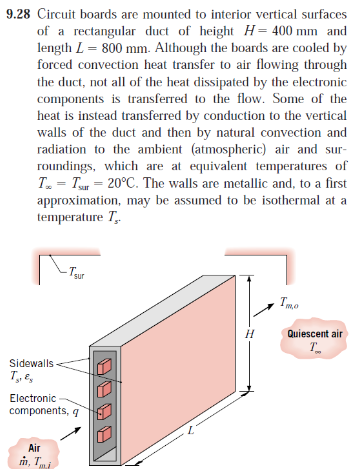

clear all
clf
format short g
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P_atm = 101325; % Pascal eller 1e5
fluid = 'air'

fluid = 'air'

u = symunit;

L = 800e-3; % m længde af duct
H = 400e-3; % m højde af duct
As = L*H % overflade arealet af en side

As =          0.32


P = 2*L + 2*H

P =           2.4


T_inf = 20 + 273.15; % =T_sur % K 
T_mo = 30 + 273.15; % K % udgangtemperatur forforced cooling
T_mi = T_inf; % luftemperatur ind
T_m = (T_mo + T_mi) /2 % K % middel temperatur til matriale værdier

T_m =        298.15


T_sur = T_inf; %overflade af metal til stråling bidrag
q_m = 0.015; % kg / s % massestrømmen af luften
q_tot = 200; % W varmen fra componenterne

k = CoolProp.PropsSI('conductivity', 'P', P_atm, 'T', T_m, fluid)

k =      0.026247


c_p = CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_m, fluid) %specificHeat_p

c_p =        1006.3


mu = CoolProp.PropsSI('viscosity', 'P', P_atm, 'T', T_m, fluid) %Dynamisk viscositet

mu =    1.8448e-05


rho = CoolProp.PropsSI('D', 'P', P_atm, 'T', T_m, fluid) %Densitet

rho =        1.1843


Pr = CoolProp.PropsSI('Prandtl', 'P', P_atm, 'T', T_m, fluid)

Pr =        0.7073


% eta = nu * rho;
nu = mu / rho

nu =    1.5577e-05



syms T_s

epsilon_15 = 0.15;
epsilon_90 = 0.90;
sigma = 5.670374419e-8; % stefan-boltzmann konstant %physconst('Boltzmann')
g = 9.82; % m/s^2 tyngde accellerationen

Vi har 3 forskellige varme overførelser

- $q_c$ forced cooling inside

- $q_{conv}$ natural cooling on sides

- $q_{rad}$ strålings bidrag fra yder siden

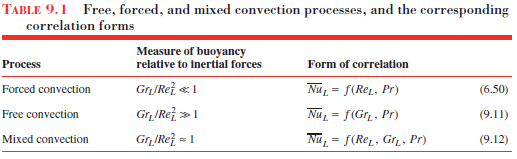

Laminar when $Ra_L \le 10^9$

for the vertical plate For laminar flow $(10^4 < Ra_L < 10^9)$

**a)**

% rho_s = CoolProp.PropsSI('D', 'P', P_atm, 'T', 308.82768, fluid); %Densitet
% rho_inf = CoolProp.PropsSI('D', 'P', P_atm, 'T', 308.82768, fluid); %Densitet

% beta = - (-rho_inf + 308.82768) / (rho_s * (T_inf - T_s)); % normally for liqueds and non ideal gasses
beta = 1 / T_m

beta =      0.003354


Gr_L = g * beta * (T_s - T_inf) * H^3 / nu^2; % Grashof number

Ra_L = Gr_L * Pr; % Rayleigh number
% vpa(Ra_L)

Vi antager laminar flow og bruger 9.26

% L_c = As / P % for horisontal plates
L_c = H; % den charictaristiske længde for en lodret flade er fladen højde.

Nu_L = (0.825 + 0.387 * Ra_L^(1/6) / ( 1 + (0.492/Pr)^(9/16) )^(8/27) )^2; % ligning 9.26

h = Nu_L * k / L_c;

q_c = q_m * c_p * (T_mo - T_mi) % forced cooling bidrag

q_c =        150.95





q_conv = As * h * (T_s - T_inf) * 2; % (naturlig convection for begge sider)

q_rad = epsilon_15 * As * sigma * (T_s^4 -T_sur^4) * 2; % stråling fra begge sider

q_eq = q_tot == q_c + q_conv + q_rad;
T_s_sol = vpa(solve(q_eq,T_s), 8)

$$T\_s\_sol = \left(\begin{array}{c} 308.82768\\ 323.40387-1142.8067\,\mathrm{i}\\ 323.40387+1142.8067\,\mathrm{i} \end{array}\right)$$

T_s_K = T_s_sol(1)

$$T\_s\_K = 308.82768192507637650123797357082$$

T_s_C = T_s_sol(1) - 273.15

$$T\_s\_C = 35.67768192507639923860551789403$$


q_conv_sol = double(subs(q_conv,T_s,T_s_K))

q_conv_sol =        39.739


q_rad_sol = double(subs(q_rad,T_s,T_s_K))

q_rad_sol =        9.3147


Doublet tjek om laminar

Gr_L = double(g * beta * (T_s_K - T_inf) * H^3 / nu^2) % Grashof number

Gr_L =     1.362e+08


Ra_L = Gr_L * Pr % Rayleigh number

Ra_L =    9.6333e+07


**b)**

Gr_L = g * beta * (T_s - T_inf) * H^3 / nu^2; % Grashof number
Ra_L = Gr_L * Pr; % Rayleigh number
Nu_L = (0.825 + 0.387 * Ra_L^(1/6) / ( 1 + (0.492/Pr)^(9/16) )^(8/27) )^2; % ligning 9.26
h = Nu_L * k / L_c;

q_c = q_m * c_p * (T_mo - T_mi) % forced cooling bidrag

q_c =        150.95



q_conv = As * h * (T_s - T_inf) * 2; % (naturlig convection for begge sider)

q_rad = epsilon_90 * As * sigma * (T_s^4 -T_sur^4) * 2; % stråling fra begge sider

q_eq = q_tot == q_c + q_conv + q_rad;
T_s_sol = vpa(solve(q_eq,T_s), 8)

$$T\_s\_sol = \left(\begin{array}{c} 301.94421\\ 105.36417-629.7368\,\mathrm{i}\\ 105.36418+629.7368\,\mathrm{i} \end{array}\right)$$

T_s_K = T_s_sol(1)

$$T\_s\_K = 301.94420944048641786139342002571$$

T_s_C = T_s_sol(1) - 273.15

$$T\_s\_C = 28.794209440486440598760964348912$$


q_conv_sol = double(subs(q_conv,T_s,T_s_K))

q_conv_sol =        18.781


q_rad_sol = double(subs(q_rad,T_s,T_s_K))

q_rad_sol =        30.273


Doublet tjek om laminar

Gr_L = double(g * beta * (T_s_K - T_inf) * H^3 / nu^2) % Grashof number

Gr_L =    7.6399e+07


Ra_L = Gr_L * Pr % Rayleigh number

Ra_L =    5.4037e+07


**c)**

epsilons = [epsilon_15, epsilon_90];
for i = 1:length(epsilons)
    Gr_L = g * beta * (T_s - T_inf) * H^3 / nu^2; % Grashof number
    Ra_L = Gr_L * Pr; % Rayleigh number
    Nu_L = (0.825 + 0.387 * Ra_L^(1/6) / ( 1 + (0.492/Pr)^(9/16) )^(8/27) )^2; % ligning 9.26
    h = Nu_L * k / L_c;
    
    q_c = 0; % forced cooling bidrag
    
    q_conv = As * h * (T_s - T_inf) * 2; % (naturlig convection for begge sider)
    
    q_rad = epsilons(i) * As * sigma * (T_s^4 -T_sur^4) * 2; % stråling fra begge sider
    
    q_eq = q_tot == q_c + q_conv + q_rad;
    T_s_sol = vpa(solve(q_eq,T_s), 8);
    T_s_K(i) = T_s_sol(1);
    T_s_C(i) = T_s_sol(1) - 273.15;
    
    q_conv_sol(i) = double(subs(q_conv,T_s,T_s_K(i)));
    q_rad_sol(i) = double(subs(q_rad,T_s,T_s_K(i)));

    Gr_Ls(i) = g * beta * (T_s_K(i) - T_inf) * H^3 / nu^2; % Grashof number
    Ra_Ls(i) = Gr_Ls(i) * Pr; % Rayleigh number
end

T_s_K = double(T_s_K)

T_s_K =        340.44       322.28


T_s_C = double(T_s_C)

T_s_C =        67.292       49.127


q_conv_sol

q_conv_sol =        167.08       88.879


q_rad_sol

q_rad_sol =        32.922       111.12


doublet tjekker om vi har ligning 9.26 kan bruges

Gr_Ls = double(Gr_Ls)

Gr_Ls =    4.1085e+08   2.5304e+08


Ra_Ls = double(Ra_Ls)

Ra_Ls =    2.9059e+08   1.7897e+08


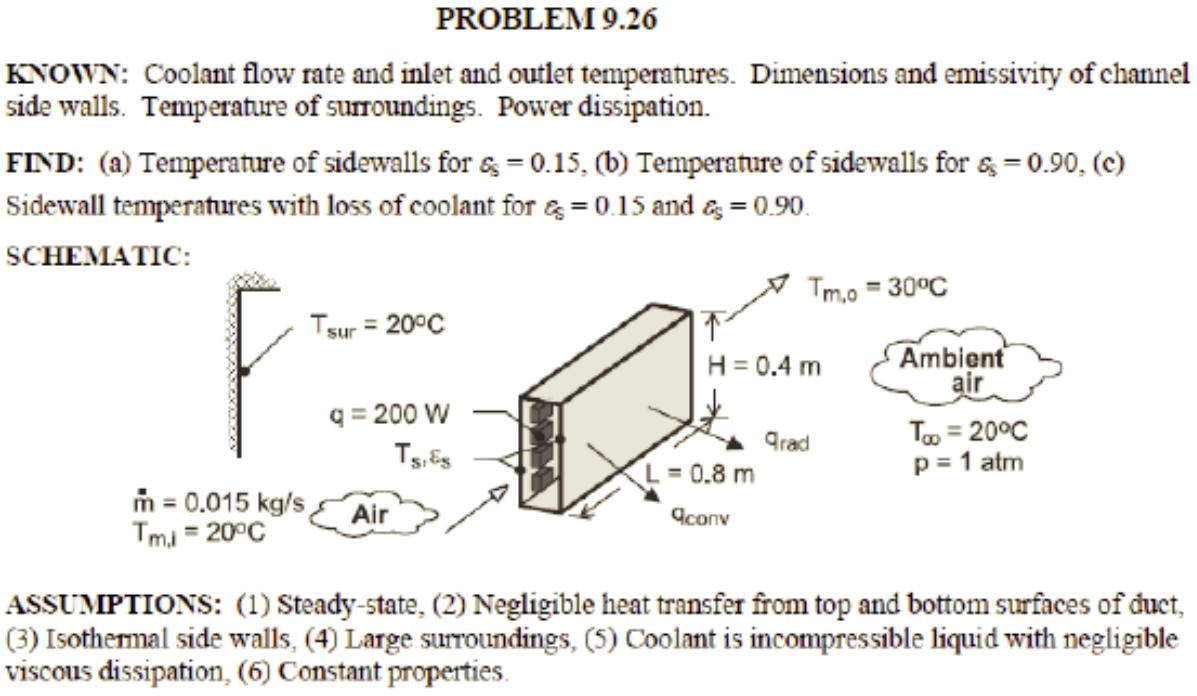

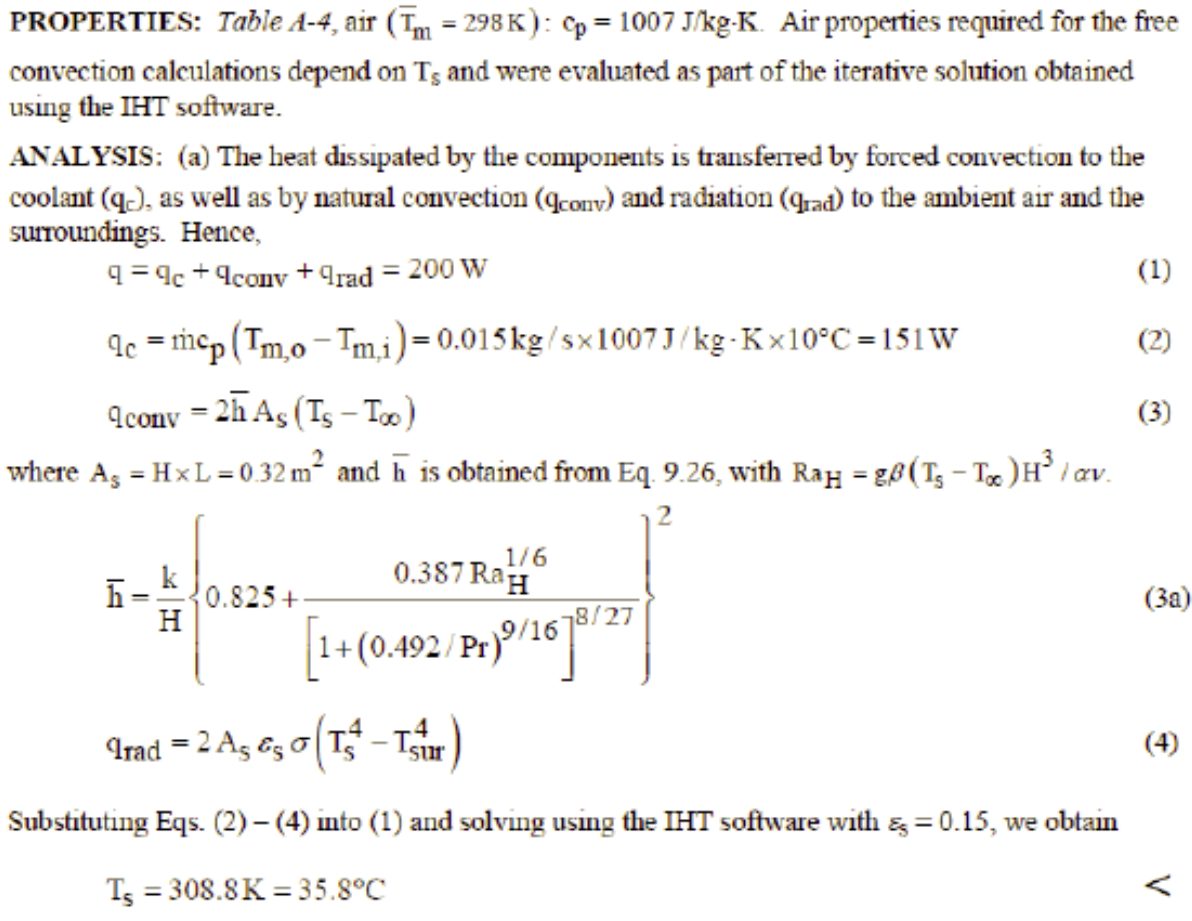

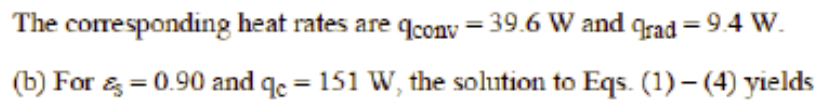

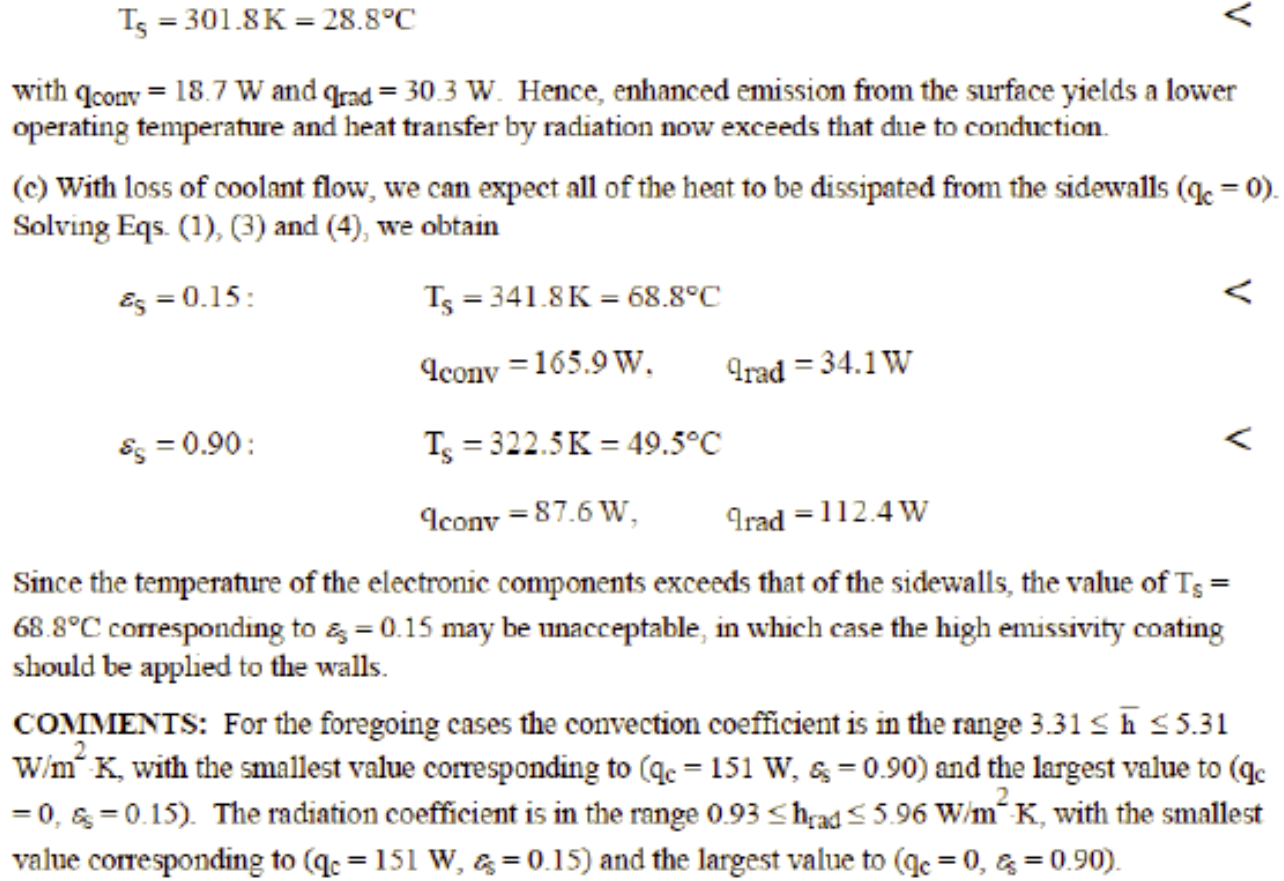

opgave 9.58 (9.52)

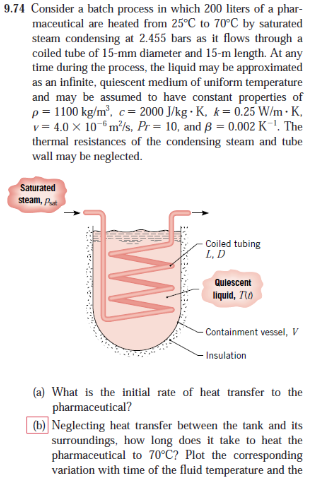

- væske betragtes som udstrækkes uendeligt

- Ensartet temperatur i væsken

clear all
clf
format short g
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P_atm = 101325; % Pascal eller 1e5
fluid = 'water'

fluid = 'water'

u = symunit;

K = 273.15; % kelvin modifier
vol = 0.200; % m^3
T_i = 25 + K; % start temperaturen
T_f = 70 + K; % slut temperatur
rho = 1100; % kg / m^3 % densitet af væsken

P_steam = 2.445e5; % Pa % trykket i den mættede damp
D = 0.015; % Diameter of pipe
L = 15; % length of pipe

c = 2000; % J/(kg * K)
k = 0.25; % W/(m*K)
nu = 4.0e-6; % m^2/s
Pr = 10; % prandtls tal
beta = 0.002; % K^-1
As = pi * D * L

As =       0.70686


h_fg = 2.183e6; % table A-4
T_steam = CoolProp.PropsSI('T', 'P', P_steam, 'Q', 1, fluid) %Densitet

T_steam =        399.83



g = 9.82; % tyngde accelerationen i Danmark

**a)**

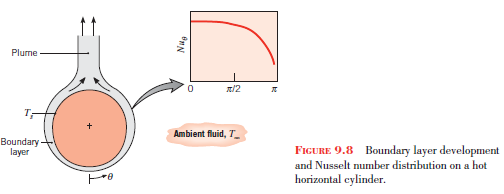

% alpha = k / (rho * c)
% alpha = nu / Pr
Gr_D = g * beta * (T_steam - T_i) * D^3 / (nu^2) % Grashof number

Gr_D =    4.2124e+05



Ra_D = Gr_D * Pr % Rayleigh number

Ra_D =    4.2124e+06


% Ra_D = g * beta * (T_steam - T_i) * D^3 / (alpha *nu) % Grashof number

$Ra_D < 10^{12}$ det er dermed laminart flow  and 9.34 is valid

Nu_D = (0.60 + 0.387 * Ra_D^(1/6) / (1 + (0.559/Pr)^(9/16) )^(8/27) )^2

Nu_D =        27.693


h = Nu_D * k / D %W/(m^2*K) % convection heat transfer coefficient

h =        461.56



q_pharm = As * h * (T_steam - T_i) % W

q_pharm =         33174


**b)**

m = vol * rho

m =    220


% dq/dt
t = m * c  * (T_f - T_i)/ q_pharm % ikkke steady state %h_fg

t =        596.86



t = 0; %start tiden
% dt = 1; %tids skridt
i = 0;
dT = 0.01; % hæver temperaturen pr skridt

fluid = 'water' %???

fluid = 'water'

rho_s = CoolProp.PropsSI('D', 'P', P_atm, 'T', T_steam, fluid) %Densitet

rho_s =       0.55519


% rho = CoolProp.PropsSI('D', 'P', P_atm, 'T', T_i, fluid) %Densitet
% beta = - (-rho + rho_s) / (rho_s * (T_i - T_steam)) % normally for liqueds and non ideal gasses

Der antage konstant beta værdi

while T_i <= T_f
    i = i + 1;
    
    c = CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_i, fluid); %specificHeat_p
    cs(i) = c;
    k = CoolProp.PropsSI('conductivity', 'P', P_atm, 'T', T_i, fluid);
    mu = CoolProp.PropsSI('viscosity', 'P', P_atm, 'T', T_i, fluid); %Dynamisk viscositet
    rho = CoolProp.PropsSI('D', 'P', P_atm, 'T', T_i, fluid); %Densitet
    Pr = CoolProp.PropsSI('Prandtl', 'P', P_atm, 'T', T_i, fluid);
    nu = mu / rho;


    % beta = - (-rho + rho_s) / (rho_s * (T_i - T_steam)); % normally for liqueds and non ideal gasses
  
    Gr_D = g * beta * (T_steam - T_i) * D^3 / (nu^2); % Grashof number
    Ra_D = Gr_D * Pr; % Rayleigh number
    Ra_Ds(i) =  Ra_D;
    Nu_D = (0.60 + 0.387 * Ra_D^(1/6) / (1 + (0.559/Pr)^(9/16) )^(8/27) )^2;
    h = Nu_D * k / D; %W/(m^2*K) % convection heat transfer coefficient

    q_pharm = As * h * (T_steam - T_i); % W
    qs(i) = q_pharm;

    dt = (m * c * dT) / q_pharm; % time to raise temperature 1 degree step
    t = t + dt;
    ts(i) = t;
    
    T_i = T_i + dT;
    T_is(i) = T_i;
    if i == 10000
        disp('emergency break')
        break
    end
end

Det antages at rør temperaturen ikkke falder

t

t =        312.98


t_initial = m * cs(1)  * (T_f - T_is(1))/ qs(1) % ikkke steady state %h_fg

t_initial =        247.86


T_test = max(T_is) - K - dT

T_test =            70


% c_test = cs(1)
% c_test = cs(end)

Vi plotter q mod T

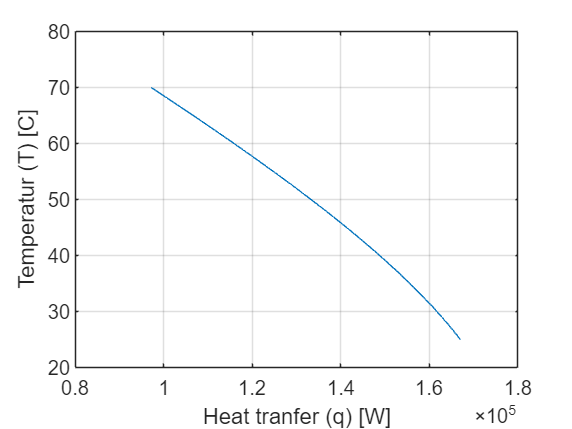

figure
plot(qs, T_is - K)
xlabel('Heat tranfer (q) [W]')
ylabel('Temperatur (T) [C]')
grid('on')

Plotter t mod T

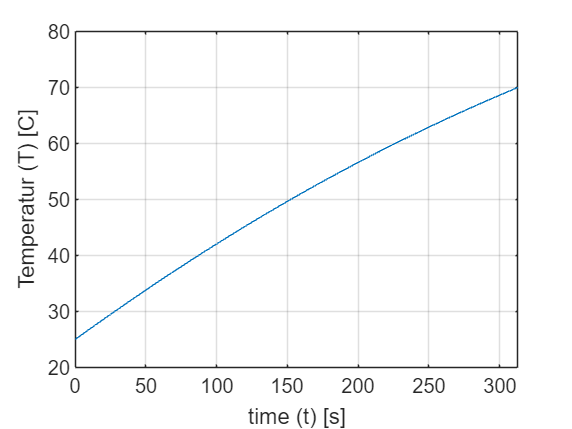

figure
plot(ts, T_is - K)
xlabel('time (t) [s]')
ylabel('Temperatur (T) [C]')
grid('on')

t mod Ra

Plotter t mod T

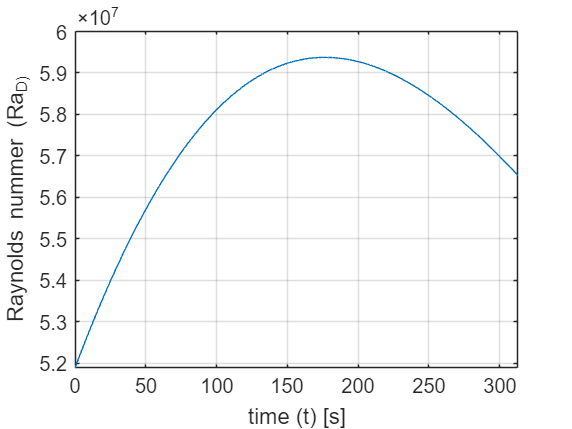

figure
plot(ts, Ra_Ds)
xlabel('time (t) [s]')
ylabel('Raynolds nummer (Ra_D)')
grid('on')

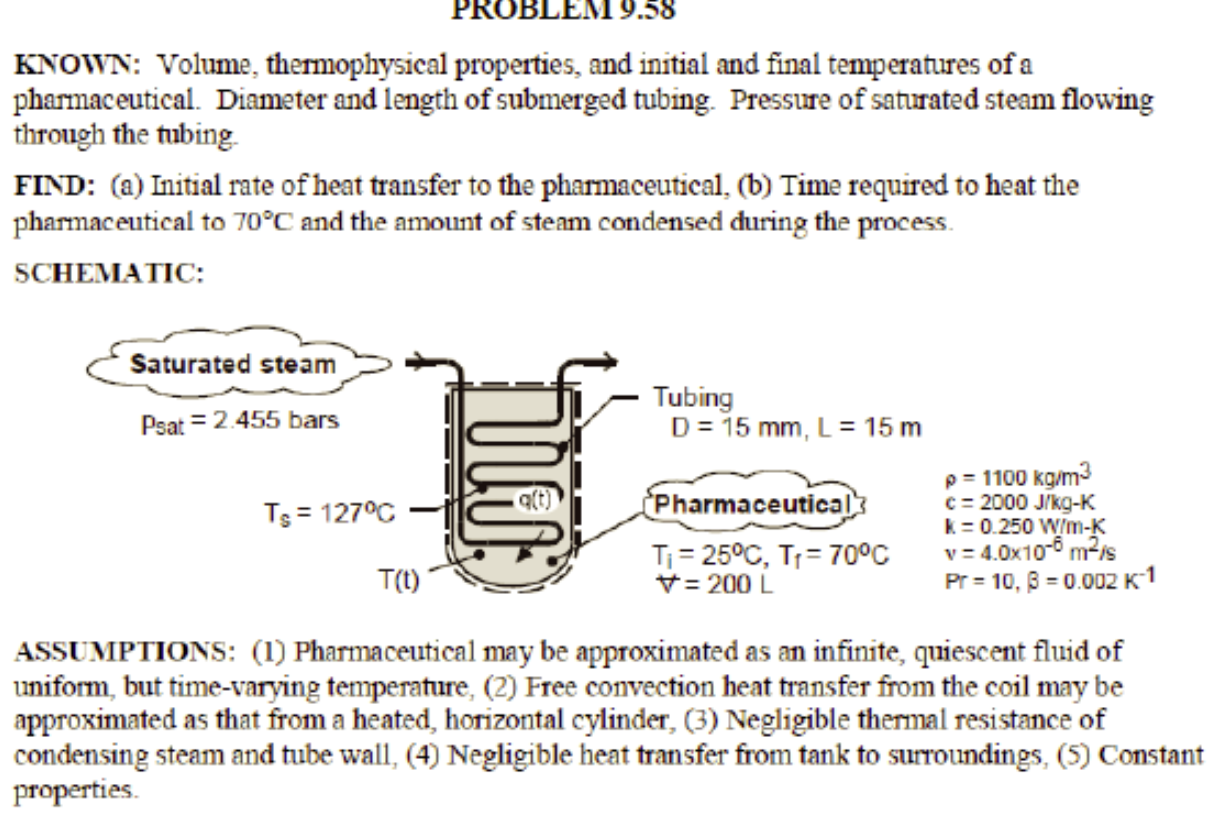

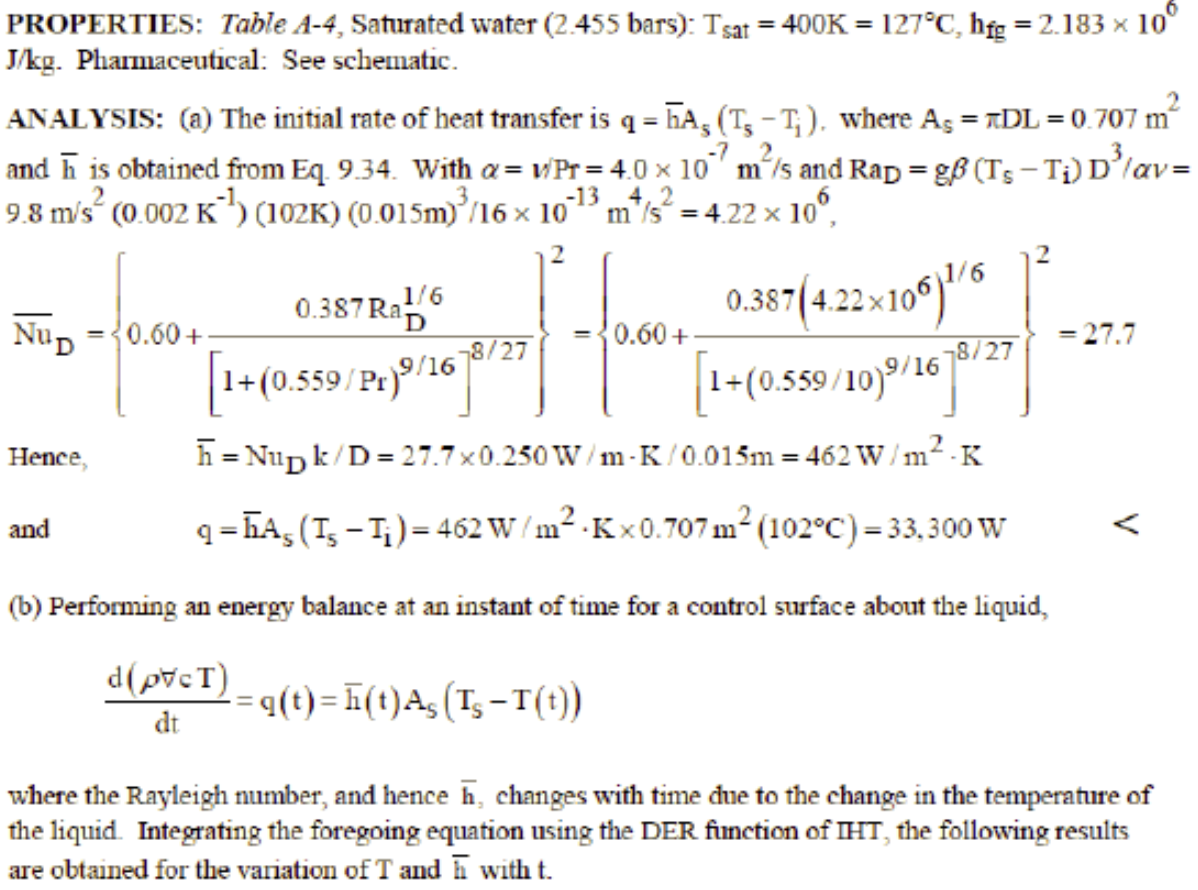

Figurer